# **Example: Iterative fitting for multiple provinces in Hubei**

## **Initialization**

The parameters are here taken as constant except the death rate and the cure rate.

clearvars;close all;clc;
[Confirmed, Deaths, Recovered, time] = load_data();
fprintf(['Most recent update: ', datestr(time(end)), '\n'])

Most recent update: 13-Jun-2020


## Iterative application of fit_SEIQRDP

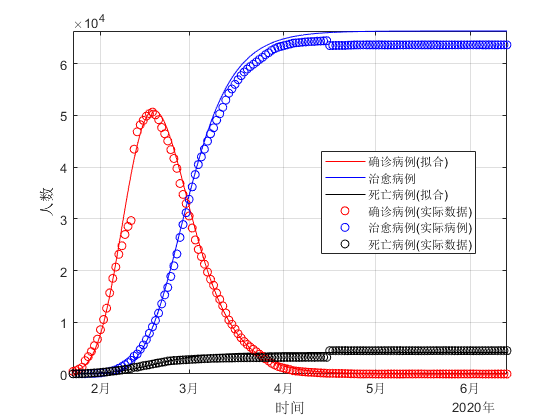

% Reshape data
num_len = length(Confirmed);
Confirmed = reshape(Confirmed, 1, num_len);
Deaths = reshape(Deaths, 1, num_len);
Recovered = reshape(Recovered, 1, num_len);
minNum= max(200,round(0.2*max(Confirmed)));
% Warning! a dummy value of Npop is used here. If you want a realistic
% value for beta, you need to specify the correct value for Npop
Npop= 59270000; % population (It affects the values of the parameters)
% for testing fitting results
% Remove case where only few infectious are recorded (to avoid bad
% initial conditions)
% Recovered(Confirmed<=minNum)=[];
% Deaths(Confirmed<=minNum)=[];
% time(Confirmed<=minNum)= [];
% Confirmed(Confirmed<=minNum)=[];
Active = Confirmed-Recovered-Deaths;
Active(Active<0) = 0; % No negative number possible
[~,indMin] = min(Active);

% The fitting is only applied if enough data is collected (that is why
% I use the case of China)
% Definition of the first estimates for the parameters
alpha_guess = 0.06; % protection rate
beta_guess = 0.8; % Infection rate
LT_guess = 3; % latent time in days
Q_guess = 0.5; % rate at which infectious people enter in quarantine
lambda_guess = [0.01,0.01,10]; % recovery rate
kappa_guess = [0.005,0.005,10]; % death rate

guess = [alpha_guess,beta_guess,1/LT_guess, Q_guess,lambda_guess,kappa_guess];

tic
% Initial conditions
Q0 = Confirmed(1)-Recovered(1)-Deaths(1);
I0 = 0.2*Q0; % Initial number of infectious cases. Unknown but unlikely to be zero.
E0 = Q0; % Initial number of exposed cases. Unknown but unlikely to be zero.
R0 = Recovered(1);
D0 = Deaths(1);
[alpha1,beta1,gamma1,delta1,Lambda1,Kappa1,lambdaFun,kappaFun] = ...
    fit_SEIQRDP(Active,Recovered,Deaths,Npop,E0,I0,time,guess,'Display','off');


dt = 1/24; % time step
time1 = datetime(time(1)):dt:datetime(time(end));
N = numel(time1);
t = [0:N-1].*dt;

% Call of the function SEIQRDP.m with the fitted parameters
[S,E,I,Q,R,D,P] = SEIQRDP(alpha1,beta1,gamma1,delta1,Lambda1,Kappa1,...
    Npop,E0,I0,Q0,R0,D0,t,lambdaFun,kappaFun);

figure
semilogy(time1,Q,'r',time1,R,'b',time1,D,'k');
hold on
semilogy(time,Active,'ro',time,Recovered,'bo',time,Deaths,'ko');
ylabel('人数')
xlabel('时间')
leg = {'确诊病例(拟合)',...
'治愈病例','死亡病例(拟合)',...
'确诊病例(实际数据)','治愈病例(实际病例)','死亡病例(实际数据)'};
legend(leg{:},'location', 'best');
%%%%%%%%%%%%%

grid on
axis tight
set(gca,'yscale','lin')

toc

历时 5.195800 秒。
